# DMDc for ATMD system

## ATMD system

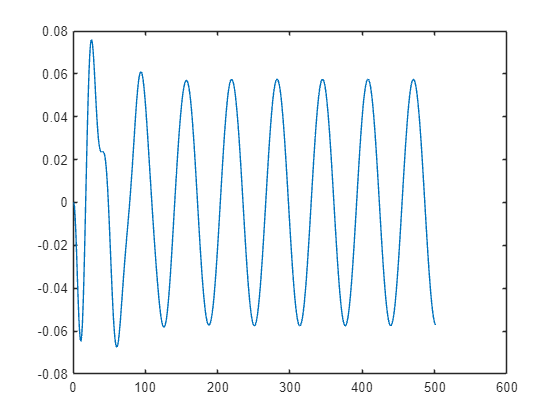

k_n = 500;
c_n = 3;
m_n = 0.68;
m_T = 0.39;
k_T = 0;
c_T = 1;

A = [          0          1                    0                   0;
        -k_n/m_n   -c_n/m_n              k_T/m_n             c_T/m_n;
               0          0                    0                   1;
         k_n/m_n    c_n/m_n   -(k_T/m_T+k_T/m_n)  -(c_T/m_T+c_T/m_n)];

B = [   0    0;
        0   -1;
        0    0;  
   -1/m_T    0];

C = [-k_n/m_n   -c_n/m_n    k_T/m_n     c_T/m_n];

D = [0  -1];

SYS = ss(A,B,C,D);

t = 0:0.01:5;
ddx_g = 1*sin(10*t);
F_T = zeros(1,length(t));

u = [ddx_g;
    F_T];

Y = lsim(SYS,u,t);

plot(Y)